# Laboratorio 1

**Diego Carvajal - Duvan Lizarazo**

## Importar la base de datos de Hepatitis

datafile = pwd + "\hepatiti.pat";
hepatiti = importHepatitis(datafile);
hepatiti = table2array(hepatiti);
hepatiti(:,20:21) = [];
hepa_c1 = hepatiti(1:33,:);
hepa_c2 = hepatiti(34:end,:);

## Tablas estadisticas clase 1

La primer fila es la media, la segunda fila es la desviación estandar, la tercera es la varianza, la cuarta es el IQR, la quinta es el skeweness, y la sexta es kurtosis.

Eliminando las columnas de clase

estadistica_c1 = zeros(6,19);
estadistica_c1(1,:) = mean(hepa_c1);
estadistica_c1(2,:) = std(hepa_c1);
estadistica_c1(3,:) = var(hepa_c1);
estadistica_c1(4,:) = iqr(hepa_c1);
estadistica_c1(5,:) = skewness(hepa_c1);
estadistica_c1(6,:) = kurtosis(hepa_c1);
estadistica_c1 = array2table(estadistica_c1);
estadistica_c1.Properties.RowNames = {'Media', 'Desviacion estandar', 'Varianza', ...
    'IQR', 'Skewness', 'Kurtosis'};
estadistica_c1.Properties.VariableNames = {'var1', 'var2', 'var3', 'var4', 'var5', ...
    'var6', 'var7', 'var8', 'var9', 'var10', 'var11', 'var12', 'var13', 'var14', ...
    'var15', 'var16', 'var17', 'var18', 'var19',};
estadistica_c1(:,estadistica_c1.Properties.VariableNames(1:6))

ans = 6×6 table
                            var1        var2       var3        var4        var5       var6  
                           _______    ________    _______    ________    ________    _______

    Media                   46.091      1.0303     1.3636      1.9394      1.0909      1.303
    Desviacion estandar     10.205     0.17408     0.4885     0.24231     0.29194    0.46669
    Varianza                104.15    0.030303    0.23864    0.058712    0.085227     0.2178
    IQR                       16.5           0          1           0           0          1
    Skewness               0.28377      5.4801    0.56695      -3.683       2.846    0.85719
    Kurtosis              

estadistica_c1(:,estadistica_c1.Properties.VariableNames(7:12))

ans = 6×6 table
                             var7       var8        var9       var10       var11      var12  
                           ________    _______    ________    ________    _______    ________

    Media                     1.697     1.8788      1.6061      1.6364      1.303      1.5758
    Desviacion estandar     0.46669    0.33143      0.4962      0.4885    0.46669     0.50189
    Varianza                 0.2178    0.10985     0.24621     0.23864     0.2178     0.25189
    IQR                           1          0           1           1          1           1
    Skewness               -0.85719    -2.3212    -0.43412    -0.56695    0.85719    -0.30657
    Kurtosis           

estadistica_c1(:,estadistica_c1.Properties.VariableNames(13:18))

ans = 6×6 table
                            var13      var14     var15     var16      var17      var18 
                           ________    ______    ______    ______    ________    ______

    Media                    1.6667    2.4964    121.24    97.353      3.1773    44.199
    Desviacion estandar     0.47871    1.8663    46.534    97.922     0.56251    12.861
    Varianza                0.22917    3.4832    2165.4    9588.7     0.31642    165.39
    IQR                           1         2     43.25        72        0.75      6.25
    Skewness               -0.70711    1.4128    1.6007    2.8086    0.029086    1.8607
    Kurtosis                    1.5    4.7078    6.3332    12

estadistica_c1(:,estadistica_c1.Properties.VariableNames(19))

ans = 6×1 table
                            var19 
                           _______

    Media                   1.7576
    Desviacion estandar    0.43519
    Varianza               0.18939
    IQR                       0.25
    Skewness               -1.2021
    Kurtosis                 2.445


## Tablas estadisticas clase 2

estadistica_c2 = zeros(6,19);
estadistica_c2(1,:) = mean(hepa_c2);
estadistica_c2(2,:) = std(hepa_c2);
estadistica_c2(3,:) = var(hepa_c2);
estadistica_c2(4,:) = iqr(hepa_c2);
estadistica_c2(5,:) = skewness(hepa_c2);
estadistica_c2(6,:) = kurtosis(hepa_c2);
estadistica_c2 = array2table(estadistica_c2);
estadistica_c2.Properties.RowNames = {'Media', 'Desviacion estandar', 'Varianza', ...
    'IQR', 'Skewness', 'Kurtosis'};
estadistica_c2.Properties.VariableNames = {'var1', 'var2', 'var3', 'var4', 'var5', ...
    'var6', 'var7', 'var8', 'var9', 'var10', 'var11', 'var12', 'var13', 'var14', ...
    'var15', 'var16', 'var17', 'var18', 'var19',};
estadistica_c2(:,estadistica_c2.Properties.VariableNames(1:6))

ans = 6×6 table
                            var1       var2        var3       var4       var5        var6  
                           _______    _______    ________    _______    _______    ________

    Media                   39.877      1.123      1.5492     1.8197      1.418      1.6885
    Desviacion estandar      12.85    0.32973     0.49963    0.38605    0.49527     0.46501
    Varianza                165.13    0.10873     0.24963    0.14903    0.24529     0.21623
    IQR                         20          0           1          0          1           1
    Skewness               0.49861     2.2964    -0.19768     -1.663    0.33237    -0.81419
    Kurtosis                3.020

estadistica_c2(:,estadistica_c2.Properties.VariableNames(7:12))

ans = 6×6 table
                            var7       var8        var9       var10      var11      var12  
                           _______    _______    ________    _______    _______    ________

    Media                   1.8197     1.8279      1.6148     1.8525     1.7623      1.9508
    Desviacion estandar    0.38605    0.37905     0.48866    0.35611    0.42743     0.21714
    Varianza               0.14903    0.14368     0.23879    0.12681     0.1827    0.047148
    IQR                          0          0           1          0          0           0
    Skewness                -1.663    -1.7371    -0.47161    -1.9877    -1.2324     -4.1695
    Kurtosis                3.765

estadistica_c2(:,estadistica_c2.Properties.VariableNames(13:18))

ans = 6×6 table
                            var13       var14     var15     var16      var17      var18  
                           ________    _______    ______    ______    _______    ________

    Media                    1.9426     1.1475    101.45    82.966     3.9777      66.571
    Desviacion estandar     0.23352    0.71301     45.89    85.946    0.53253      16.546
    Varianza               0.054532    0.50838    2105.9    7386.7    0.28358      273.78
    IQR                           0        0.5        39        60        0.4           8
    Skewness                -3.8065     2.7919     1.483    3.3092    0.26824    -0.37156
    Kurtosis                 15.489     12.048 

estadistica_c2(:,estadistica_c2.Properties.VariableNames(19))

ans = 6×1 table
                            var19 
                           _______

    Media                   1.3689
    Desviacion estandar    0.48448
    Varianza               0.23472
    IQR                          1
    Skewness               0.54362
    Kurtosis                1.2955


## Boxplot

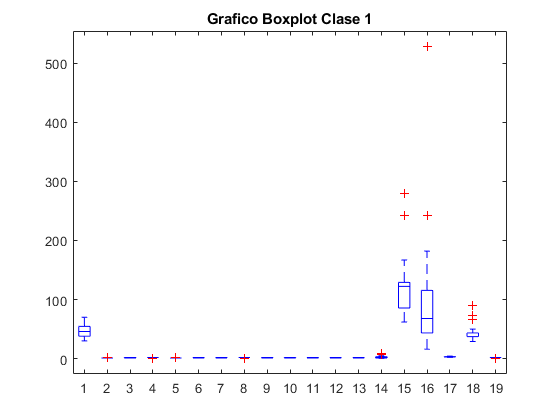

figure(1)
boxplot(hepa_c1,"Colors","b");
title("Grafico Boxplot Clase 1");

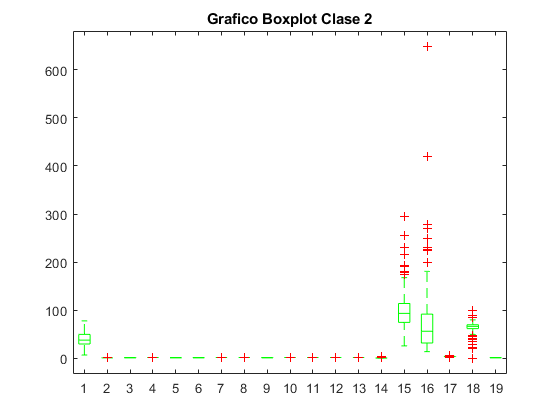

figure(2);
boxplot(hepa_c2,"Colors","g");
title("Grafico Boxplot Clase 2");

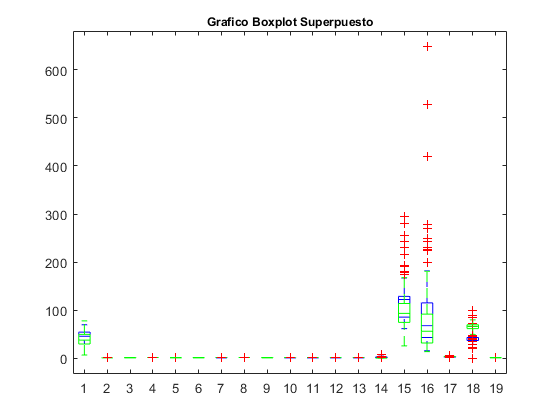

figure(3);
boxplot(hepa_c1,"Colors","b"); hold on;
boxplot(hepa_c2,"Colors", "g"); hold off;
title('Grafico Boxplot Superpuesto' ,'FontSize',9)

## Graficas estadisticas

### Desviación estandar y media

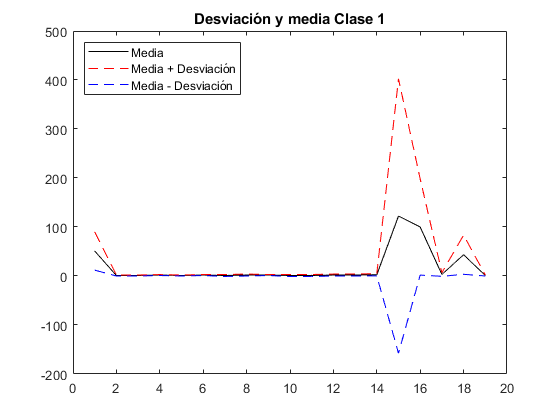

figure(4);
plot(1:19,hepa_c1(1,:),"k",1:19,hepa_c1(1,:)+hepa_c1(2,:),"r--",...
    1:19,hepa_c1(1,:)-hepa_c1(2,:),"b--");
title("Desviación y media Clase 1");
legend(["Media", "Media + Desviación", "Media - Desviación"],...
    'Location','northwest');

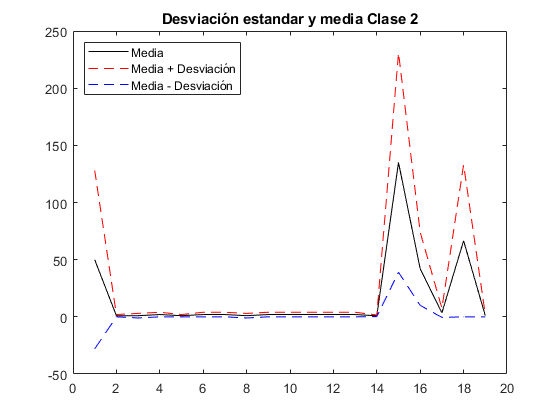

figure(5);
plot(1:19,hepa_c2(1,:),"k",1:19,hepa_c2(1,:)+hepa_c2(2,:),"r--",...
    1:19,hepa_c2(1,:)-hepa_c2(2,:),"b--");
title("Desviación estandar y media Clase 2");
legend(["Media", "Media + Desviación", "Media - Desviación"],...
    'Location','northwest');

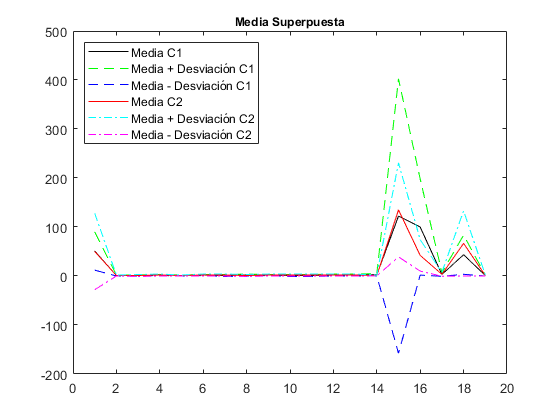

figure(6);
plot(1:19,hepa_c1(1,:),"k",1:19,hepa_c1(1,:)+hepa_c1(2,:),"g--",1:19,...
    hepa_c1(1,:)-hepa_c1(2,:),"b--",1:19,hepa_c2(1,:),"r",1:19,...
    hepa_c2(1,:)+hepa_c2(2,:),"c-.",1:19,hepa_c2(1,:)-hepa_c2(2,:),"m-."); 
title('Media Superpuesta' ,'FontSize',9);
legend(["Media C1", "Media + Desviación C1", "Media - Desviación C1", ...
    "Media C2", "Media + Desviación C2", "Media - Desviación C2"],...
    'Location','northwest');

### Rango intercuartílico

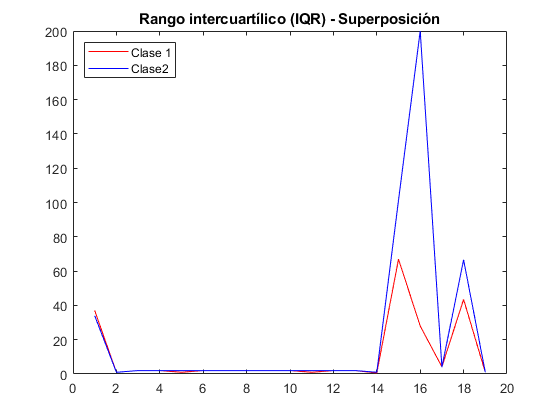

figure(7);
plot(1:19, hepa_c1(4,:),"r",1:19, hepa_c2(4,:),"b");
title("Rango intercuartílico (IQR) - Superposición");
legend(["Clase 1", "Clase2"],"Location", "northwest")

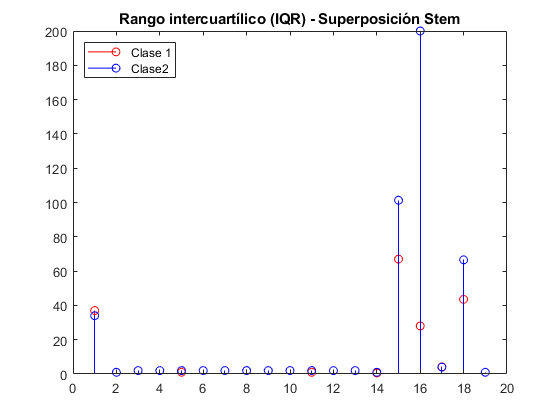

figure(8);
stem(1:19, hepa_c1(4,:),"r");
hold on;
stem(1:19, hepa_c2(4,:),"b");
hold off;
title("Rango intercuartílico (IQR) - Superposición Stem");
legend(["Clase 1", "Clase2"],"Location", "northwest")

### Asimetría estadística (Skewness)

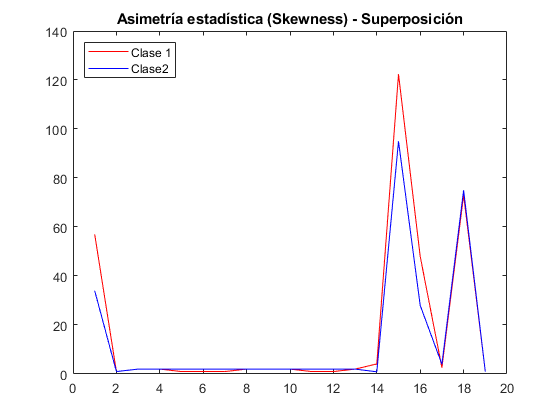

figure(9);
plot(1:19, hepa_c1(5,:),"r",1:19, hepa_c2(5,:),"b");
title("Asimetría estadística (Skewness) - Superposición");
legend(["Clase 1", "Clase2"],"Location", "northwest")

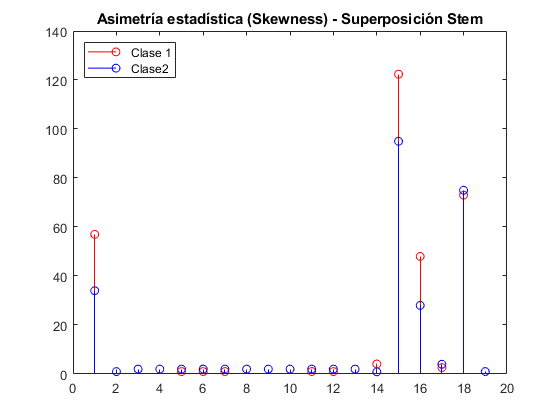

figure(10);
stem(1:19, hepa_c1(5,:),"r");
hold on;
stem(1:19, hepa_c2(5,:),"b");
hold off;
title("Asimetría estadística (Skewness) - Superposición Stem");
legend(["Clase 1", "Clase2"],"Location", "northwest")

### Curtosis (Kurtosis)

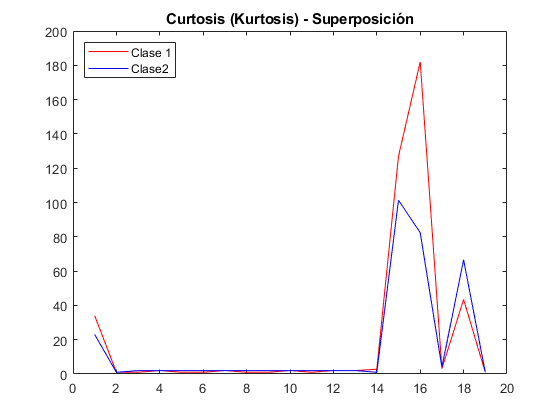

figure(11);
plot(1:19, hepa_c1(6,:),"r",1:19, hepa_c2(6,:),"b");
title("Curtosis (Kurtosis) - Superposición");
legend(["Clase 1", "Clase2"],"Location", "northwest")

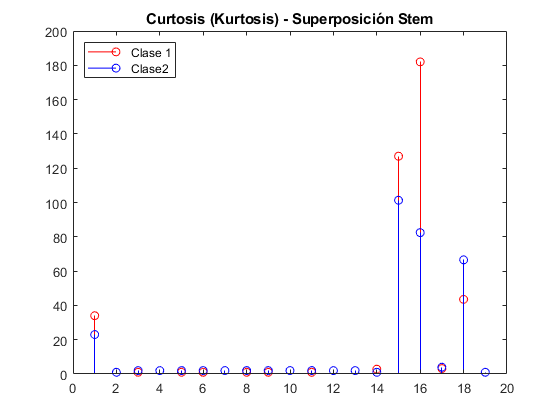

figure(12);
stem(1:19, hepa_c1(6,:),"r");
hold on;
stem(1:19, hepa_c2(6,:),"b");
hold off;
title("Curtosis (Kurtosis) - Superposición Stem");
legend(["Clase 1", "Clase2"],"Location", "northwest")